# LDPC (Low Density Parity Check Code)

# **Hard Decision Decoding**

# **Lab-3 Group-1**

% Load 5G NR LDPC base H matrix
baseGraph5GNR = 'NR_2_6_52'; % For second BG matrix NR_1_5_352

% Code rate Array
% vary this in the set {1/4, 1/3, 1/2, 3/5} for 2_6_52 and in the range {1/3, 1/2, 3/5 and 4/5} for 1_5_352
R = [1/4, 1/3, 1/2, 3/5]; 

% Convert the base H matrix to binary H matrix
[B,Hfull,z] = nrldpc_Hmatrix(baseGraph5GNR); 

% 5G NR specific details
[mb,nb] = size(B); kb = nb - mb; 

Ebnodb_range = 0 : 0.5 : 10;

% Number of Simulation
Nsim = 500;

% Number of max Iteration
max_itr = 20;

% Storage for graph Plot of Bit Error Rate(BER) vs Eb/No(dB) 
BER = zeros(length(R), length(Ebnodb_range));

% Storage for graph Plot of Error Probability vs Eb/No(dB)
p_error = zeros(length(R), length(Ebnodb_range));

% Storage for graph Plot of Success Probabilty vs No of Iteration
p_success_itr = zeros(length(Ebnodb_range), max_itr);

% Index for coderate 
ind_cr = 1;
        

for codeRate = R

    kNumInfoBits = kb * z; % Number of information bits
    k_pc = kb-2; nbRM = ceil(k_pc/codeRate)+2; % Some 5G NR specific details 
    nBlockLength = nbRM * z; % Number of encoded bits
    
    n = nBlockLength; % length of codeword
    
    % Next three lines are some 5G NR specific details
    H = Hfull(:,1:nBlockLength); 
    nChecksNotPunctured = mb*z - nb*z + nBlockLength;
    H = H(1:nChecksNotPunctured,:); % this is the binary H matrix
    
    % Nchecks = size(H,1); % Number of CNs (we have denoted this as U = N - K in the class)
    
    [row, col] = size(H);
    
     % Index for Ebno Loop
    ebno_itr = 1;
    
    for ebnodb = Ebnodb_range
    
        Ebno = 10 ^ (ebnodb / 10); % Convert to Decimal scale
        
        sigma = sqrt(1 / (2 * codeRate * Ebno));  % standard deviation of Gaussion Noise
    
        for i = 1 : 1 : Nsim

            b = randi([0 1],[kNumInfoBits 1]); % Generate information (or message) bit vector

            c = nrldpc_encode(B,z,b'); % Encode using 5G NR LDPC base matrix 
            c = c(1:nBlockLength); % Encoded Message

            s = 1 - 2 * c; % BPSK Modulator

            r = s + sigma * randn(1, n); % AWGN Channel

            r = r < 0; % BPSK decoder

            % L - Adjacency Matrix for Tanner Graph
            % Row's of L represent Check nodes
            % Col's of L represent Variable nodes

            % Intialize L matrix with Received codeword
            L = r .* H;

            sum_r = r;
            prev_decoded_msg = r < 0;

            for itr = 1 : 1 : max_itr

                % SPC code
                for ir = 1 : 1 : row
                    ind = find(H(ir, :) ~= 0);
                    sum_row = sum(L(ir, ind));
                    L(ir, ind) = mod(sum_row + L(ir, ind), 2);
                end

                % Repetation code
                for ic = 1 : 1 : col
                    ind = find(H(:, ic) ~= 0);
                    cnt1 = sum(L(ind, ic)) + r(ic);
                    sum_r(ic) = (cnt1 > (length(ind) + 1)/2);
                    L(ind, ic) = (cnt1 - L(ind, ic)) > (length(ind)/2);
                end
                decoded_msg = sum_r;

                % Check if the decoded message matches the original message (c) and if the code rate index is 1 
                if(sum(xor(decoded_msg,c))==0 & ind_cr==2)
                    p_success_itr(ebno_itr, itr) = p_success_itr(ebno_itr, itr) + 1;
                end 

                % Below Code is commented out for plotting of
                % p_success vs iteration

                % if(itr ~= 1 & decoded_msg == prev_decoded_msg)
                %      break;
                % else
                %     prev_decoded_msg = decoded_msg;
                % end

            end


            % Check if successful decoded or not
            bitError = sum(decoded_msg ~=  c);
            if(bitError > 0)
                BER(ind_cr, ebno_itr) = BER(ind_cr, ebno_itr) + bitError;
                p_error(ind_cr, ebno_itr) = p_error(ind_cr, ebno_itr) + 1;
            end
            
        end    
        BER(ind_cr, ebno_itr) = BER(ind_cr, ebno_itr) / n / Nsim;
        p_error(ind_cr, ebno_itr) = p_error(ind_cr, ebno_itr) / Nsim;
        ebno_itr = ebno_itr + 1;
    
    end
    ind_cr = ind_cr + 1;

end

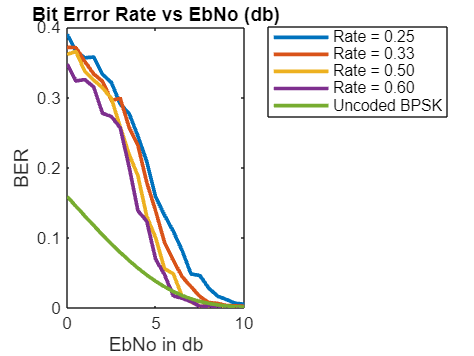

% Uncoded BPSK

% Convert SNR from dB to linear scale
Ebno = 10 .^ (Ebnodb_range ./ 10);

% Calculate Bit Error Rate (BER) for each SNR
ber_uncoded = 0.5 * erfc(sqrt(Ebno ./ 2));

for i = 1:1:4
    plot(Ebnodb_range, BER(i, :), 'DisplayName',sprintf('Rate = %.2f', R(i)), LineWidth=2);
    hold on;
end
plot(Ebnodb_range, ber_uncoded, 'DisplayName', 'Uncoded BPSK', LineWidth=2)
legend('show','Location','bestoutside');
title('Bit Error Rate vs EbNo (db)');
xlabel('EbNo in db');
ylabel('BER');
hold off;

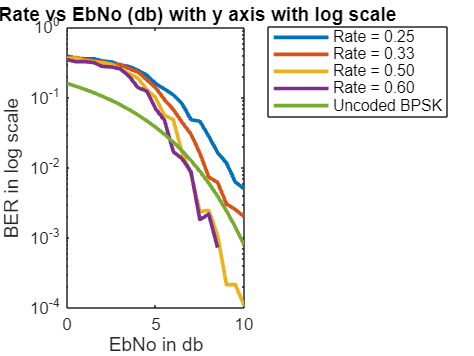


for i = 1:1:4
    semilogy(Ebnodb_range, BER(i, :), 'DisplayName',sprintf('Rate = %.2f', R(i)), LineWidth=2);
    hold on;
end
semilogy(Ebnodb_range, ber_uncoded, 'DisplayName', 'Uncoded BPSK', LineWidth=2)
legend('show','Location','bestoutside');
title('Bit Error Rate vs EbNo (db) with y axis with log scale')
xlabel('EbNo in db');
ylabel('BER in log scale');
hold off;

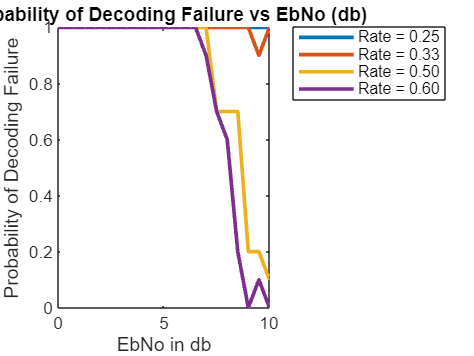


for i = 1:1:4
    plot(Ebnodb_range, p_error(i, :), 'DisplayName',sprintf('Rate = %.2f', R(i)), LineWidth=2);
    hold on;
end
legend('show','Location','bestoutside');
title('Probability of Decoding Failure vs EbNo (db)');
xlabel('EbNo in db');
ylabel('Probability of Decoding Failure');
hold off;

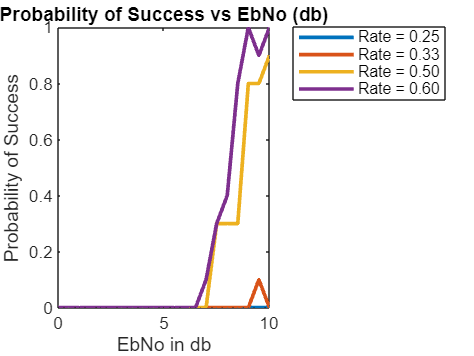


for i = 1:1:4
    plot(Ebnodb_range, 1 - p_error(i, :), 'DisplayName',sprintf('Rate = %.2f', R(i)), LineWidth=2);
    hold on;
end
legend('show','Location','bestoutside');
title('Probability of Success vs EbNo (db)');
xlabel('EbNo in db');
ylabel('Probability of Success');
hold off;

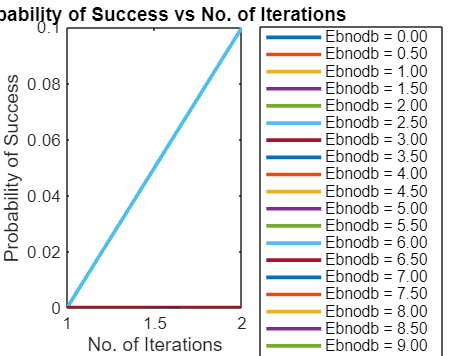


for i = 1:1:length(Ebnodb_range)
    plot(1:1:max_itr, p_success_itr(i, :)/Nsim, 'DisplayName',sprintf('Ebnodb = %.2f', Ebnodb_range(i)), LineWidth=2);
    hold on;
end
legend('show','Location','bestoutside');
title('Probability of Success vs No. of Iterations');
xlabel('No. of Iterations');
ylabel('Probability of Success');
hold off;

function y = mul_sh(x, k) % Function for shifting matrix x by k positions
% x - input matrix
% k - shift or -1
% y - output matrix


if(k == -1)
    y = zeros(1, length(x));
else
    y = [x(k+1 : end) x(1 : k)];
end

end

% Function to find Binary H matrix from Base Matrix
function [B,H,z] = nrldpc_Hmatrix(BG)

load(sprintf('%s.txt',BG),BG);
B = NR_2_6_52; % change for 2nd Base matrix
[mb,nb] = size(B);
z = 52; % change for 2nd Base matrix
H = zeros(mb*z,nb*z); 
Iz = eye(z); I0 = zeros(z);
for kk = 1:mb
    tmpvecR = (kk-1)*z+(1:z);
    for kk1 = 1:nb
        tmpvecC = (kk1-1)*z+(1:z);
        if B(kk,kk1) == -1
            H(tmpvecR,tmpvecC) = I0;
        else
            H(tmpvecR,tmpvecC) = circshift(Iz,-B(kk,kk1));
        end
    end
end


[U,N]=size(H); K = N-U;
P = H(:,1:K);
G = [eye(K); P];
Z = H*G;

end

% Function to encode message using Base Matrix
function cword = nrldpc_encode(B,z,msg)

%B: base matrix
%z: expansion factor
%msg: message vector, length = (#cols(B)-#rows(B))*z
%cword: codeword vector, length = #cols(B)*z


[m,n] = size(B);


cword = zeros(1,n*z);
cword(1:(n-m)*z) = msg;


%double-diagonal encoding
temp = zeros(1,z);
for i = 1:4 %row 1 to 4
    for j = 1:n-m %message columns
        temp = mod(temp + mul_sh(msg(((j-1)*z+1):(j*z)),B(i,j)),2);
    end
end
if B(2,n-m+1) == -1
    p1_sh = B(3,n-m+1);
else
    p1_sh = B(2,n-m+1);
end


cword((n-m)*z+1:(n-m+1)*z) = mul_sh(temp,z-p1_sh); %p1
%Find p2, p3, p4
for i = 1:3
    temp = zeros(1,z);
    for j = 1:n-m+i
        temp = mod(temp + mul_sh(cword(((j-1)*z+1):(j*z)),B(i,j)),2);
    end
    cword((n-m+i)*z+1:(n-m+i+1)*z) = temp;
end


%Remaining parities
for i = 5:m
    temp = zeros(1,z);
    for j = 1:n-m+4
        temp = mod(temp + mul_sh(cword(((j-1)*z+1):(j*z)),B(i,j)),2);        
    end
    cword((n-m+i-1)*z+1:(n-m+i)*z) = temp;    
end
end